3.22 & 3.23

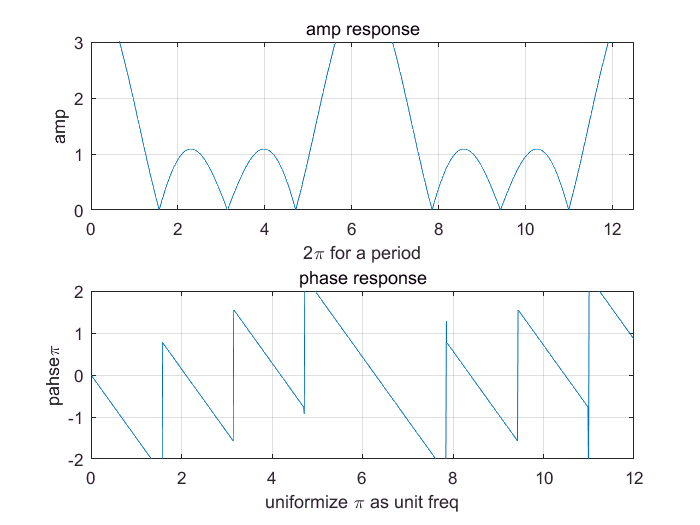

figure(1);
y = zeros(1,51);
y(1:4) = 1;
k = 0:1000;
n = 0:50;
w=2*pi/500*k;
X=y*exp(-1i.*n'*w);
subplot(2,1,1),plot(w,abs(X)),title('amp response'),grid,ylabel('amp'),xlabel('2\pi for a period');
axis([0 12.5 0 3]);
subplot(2,1,2),plot(w,angle(X)),title('phase response'),grid,ylabel('pahse\pi'),xlabel('uniformize \pi as unit freq');
axis([0 12 -2 2])

Length = 4 DFT

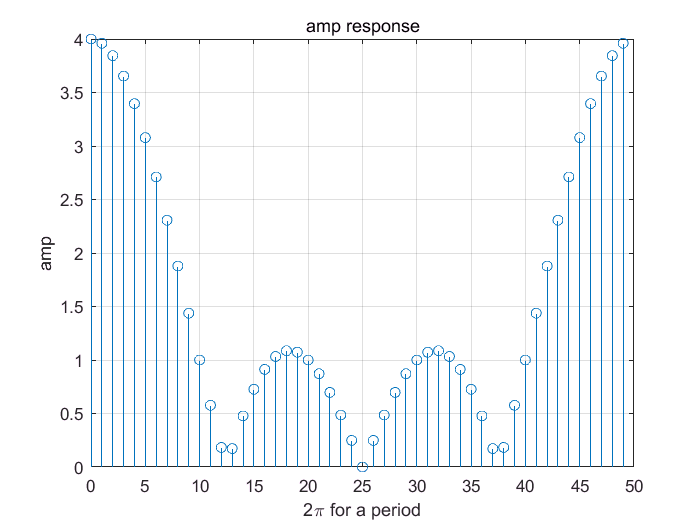

figure(2);
x = 0:49;
% if it is necessary, simply pass in 4|8 alternatively
result_dft_50 = dft(y(1:50),50);
stem(x,abs(result_dft_50)),title('amp response'),grid,ylabel('amp'),xlabel('2\pi for a period');

3.24 x(n) = 10*(0.8)^n

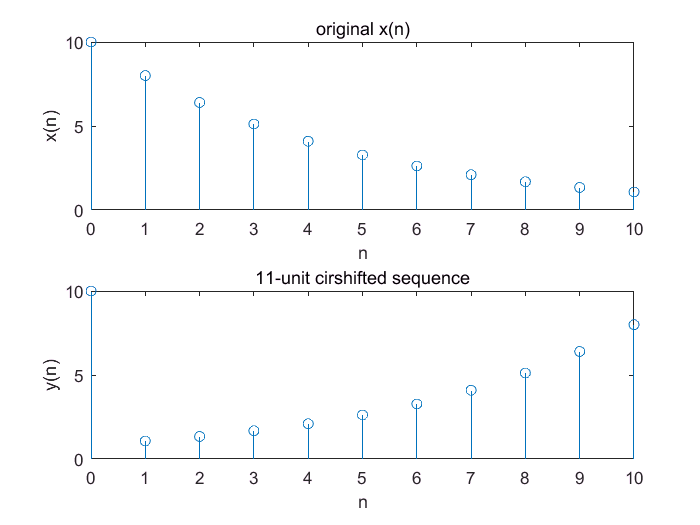

figure(3);
n = 0:10;
x = 10*(0.8).^n;
N = 11;
y = cirshift(x,10,N);
subplot(2,1,1);
stem(n,x);title('original x(n)');
xlabel('n');ylabel('x(n)');
subplot(2,1,2);
stem(n, y);
stem(fliplr(n),y);
title('11-unit cirshifted sequence');
xlabel('n');ylabel('y(n)');

3.26 (1) 5位循环卷积

        (2) 8位循环卷积

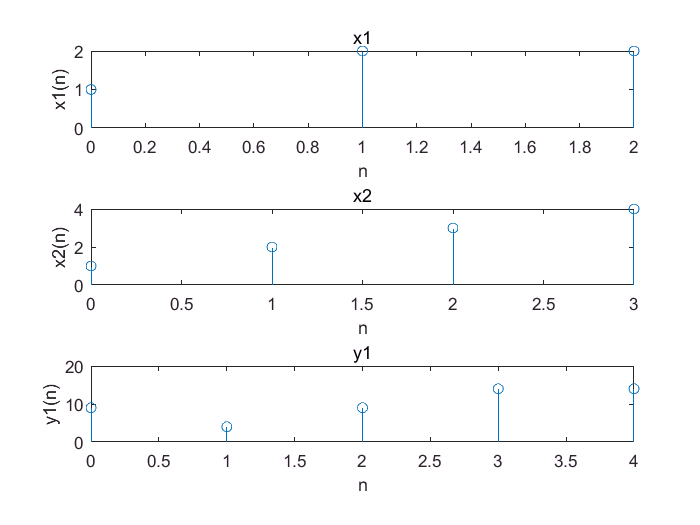

figure(4);
n = 0:4;
x1 = [1,2,2];
x2 = [1,2,3,4];
N = 5;
y1 = circonvt(x1,x2,N);
subplot(3,1,1);stem(n(1:3),x1);title('x1')
xlabel('n');ylabel('x1(n)');
subplot(3,1,2);stem(n(1:4),x2);title('x2')
xlabel('n');ylabel('x2(n)');
subplot(3,1,3);stem(n,y1);title('y1')
xlabel('n');ylabel('y1(n)');

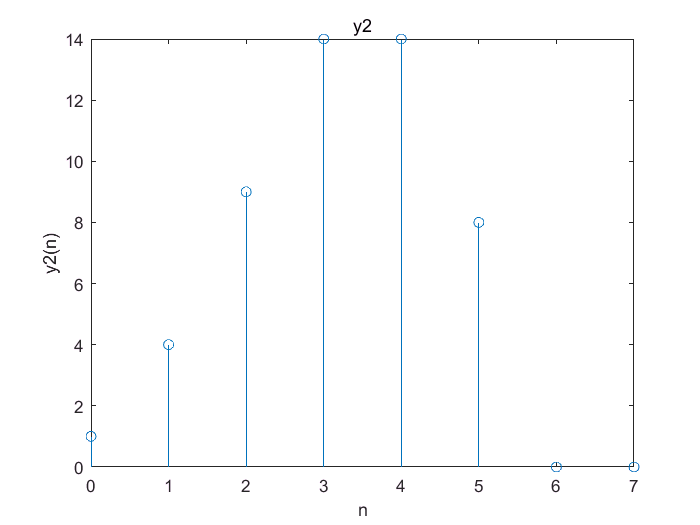

figure(5);
n2 = 0:7;
N2 = 8;
y2 = circonvt(x1,x2,N2);
stem(n2,y2);title('y2');
xlabel('n');ylabel('y2(n)');

3.28 FFT for random sequence

(time-consumption display with N=1000)

figure(6);
n = 0:1000;
xn = cos(0.47*pi*n(1:1001))+cos(0.53*pi*n(1:1001));
tic
yn_fft = fft(xn,1001);
toc 

时间已过 0.043932 秒。


subplot(2,1,1);
stem(n(1:1001),abs(yn_fft));title('fft-11');
% result_dft_50 = dft(y(1:50),50);
% von Neumann structure does not support heterogeneous-tensor calculation
tic
yn_dft = dft(xn(1:1001),1001);
toc

时间已过 0.721068 秒。


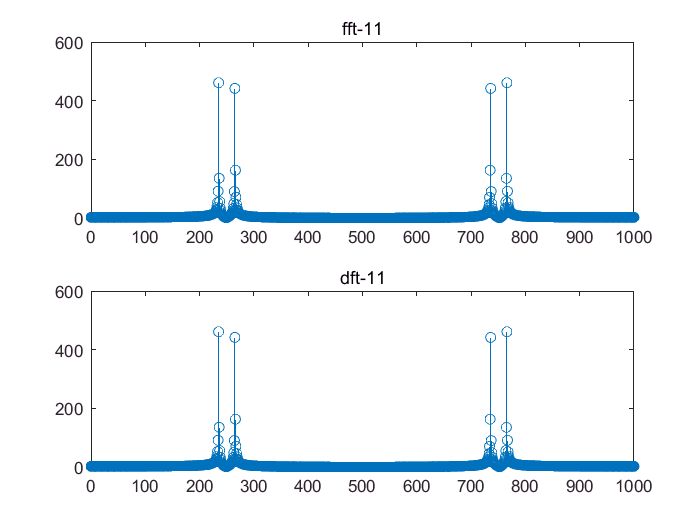

subplot(2,1,2);
stem(n(1:1001),abs(yn_dft));title('dft-11');

append null point to the end of former length-11 sequence

figure(7);
n = 0:1000;
xn_append = zeros(1,1001);
xn_append(1:1001) = xn(1:1001);
tic
yn_append_fft = fft(xn_append,1001);
toc

时间已过 0.056384 秒。


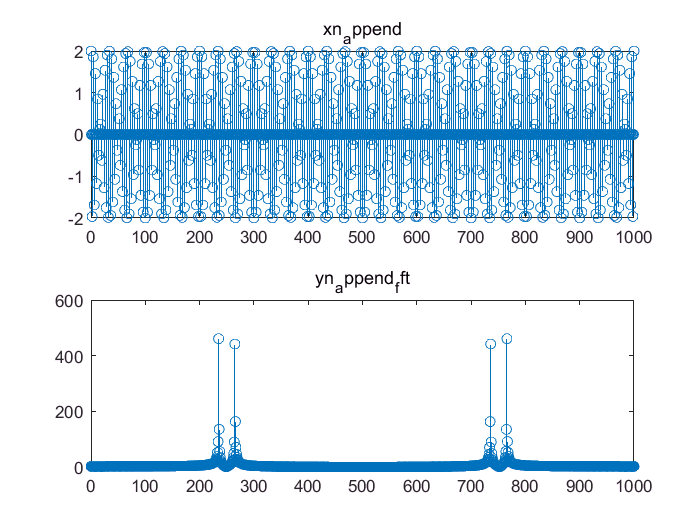

subplot(2,1,1);
stem(n(1:1001),xn_append);title('xn_append');
subplot(2,1,2);
stem(n(1:1001),abs(yn_append_fft));title('yn_append_fft');

[0.01Hz , 10Hz] amplitude spectrum

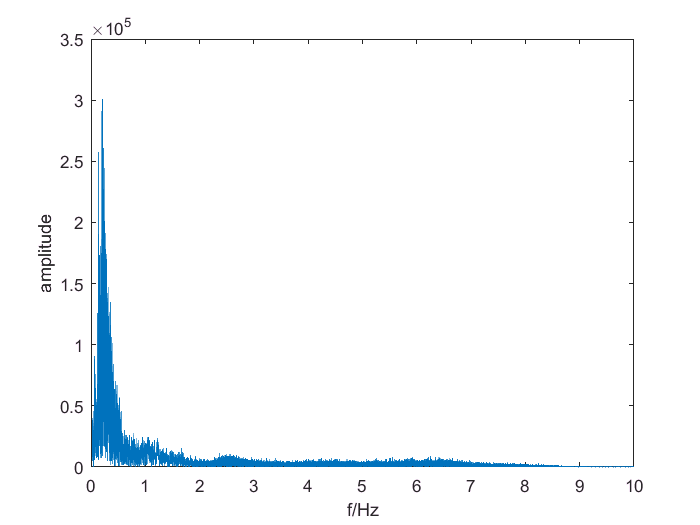

figure(8);
fid=fopen('XAN.BHZ.00.ori.SAC','r','ieee-le');
A=fread(fid,[70,1],'float32');
B=fread(fid,[40,1],'int32');
C=char(fread(fid,[1,192],'char'));
HR=fread(fid,'float32');
A(A==-12345.0)=NaN;
B(B==-12345)=NaN;
fclose(fid);
% tranform into row-vector
y=fft(HR');
n=0:length(HR)-1;
plot(n(ceil(length(n)/1000):length(HR))*20/76001,abs(y(ceil(length(n)/1000):length(HR))));axis([0 10 0 3.5*10^5]);
xlabel('f/Hz'),ylabel('amplitude');